# ProbRwdDelay

## Task

### Code availability

Codes can be found in the 2023-prob-outcome/prob-rwd-delay directory (https://github.com/stevenerrington/2023-prob-outcome/tree/main/prob-rwd-delay), with other dependencies available in the toolbox (https://github.com/stevenerrington/toolbox).

For Monosov lab users, I put a copy of the last working version of the task code (2024-04-01) on the shared drive:** share2/Steven/task-library/2023-probrwddelay**

### Summary

In this task, monkeys are presented with two offers. These offers have two attributes: the probability of large reward, and the probability of long delay. These attribute can be delivered in either order (reward then delay, or delay then reward). From March 18th 2024 onwards, the task was designed such that the attribute presentation was uncorrelated between offers. Prior to this date, the offers were correlated (offer 1 and 2 both were reward then delay, or delay then reward). Monkeys are required to gaze at an offer for 0.5 seconds in order to select it.

### Key experimental script variables

Most of these variables are defined in the _next.m file.

**c.outcomechannel**: the solenoid/reward delivery channel (may change between rigs)

**c.first_offer_idx**: determines which offer will be presented first (left or right)

**c.attribute_order_pres**: determines whether reward attribute first (1) or delay attribute first (2)

**c.rwd_delay**: the short (array position 1), medium (array position 2) and long (array position 3) delay in seconds

**c.rewarddist**: the small (1), medium (2), and large (3) reward magnitude in solenoid opening time (ms).

**rew_mag_offer1/rew_mag_offer1**: the probilities for large reward. These are set at -50 (50% large), 0 (0% large), 50 (100% medium), and 100 (100% large)

**delay_mag_offer1/delay_mag_offer2**: the probilities for long delay. These are set at -50 (50% long), 0 (0% long), 50 (100% medium), and 100 (100% long)

Variables related to the timing of the events is also found in the _next file. Here are some examples:

% c.intraoffer_interval = 0.5; % Time between offer 1 and offer 2 presentation
% c.offer_display_period = 0.0; % Time for which both offers are displayed after choice has been made
% c .choice_reveal_dur = 1.0; % Time between choice displayed and the delay reveal presentation
% c.delayreveal_timer_dur = 1.0; % Time between delay reveal and the start of the timer
% c.timer_rwdreveal_dur = 0.0; % Time between timer completion and reward reveal
% c.rwdreveal_rwddel_dur = 1.0; % Time between reward reveal and reward delivery
% c.rwddel_iti_dur = 0.5; % Time between reward delivery and ITI start

These variables are used in the _run.m script to time changes between states.

### States

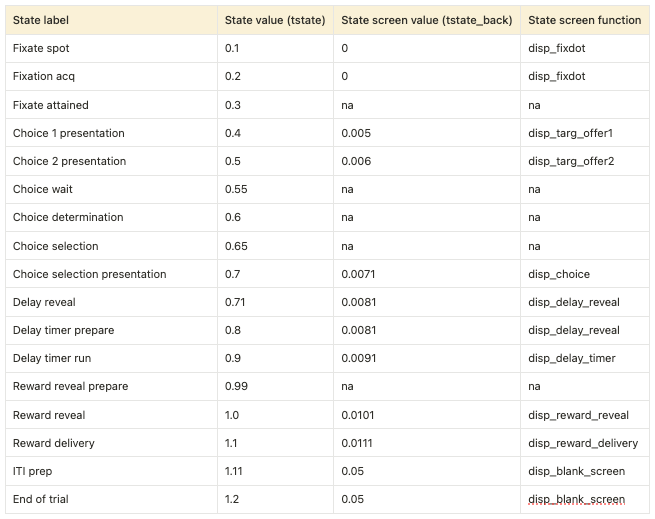

## Analysis

### Code availability

Codes can be found in the 2023-prob-outcome/prob-rwd-delay directory (https://github.com/stevenerrington/2023-prob-outcome/tree/main/prob-rwd-delay), with other dependencies available in the toolbox (https://github.com/stevenerrington/toolbox).

For Monosov lab users, I put a copy of the last working version (2024-04-01) of the code on the shared drive:** share2/Steven/shared-library/prob-rwd-delay**

### Data structure

### Analysing single-session data

#### Setup workspace and load file

Here, we define the data directory and the file of interest, and load in the PDS variable

% Define file directory and name
data_dir = '/Users/stevenerrington/Desktop/ProbRwdDelay Data/Slayer'
file = 'ProbRwdDelay_08_04_2024_11_43'

% Load file
load(fullfile(data_dir,file),'PDS')

#### Extract key behavior metrics and datatable

We then extract the datatable (summarizing trial-by-trial offer information and choice information)

% Get data table and summary probabilities
outstruct = gen_online_beh_multi(PDS);

#### Plot p(choice) behavioral summary

We then take this data and plot it to see the information more clearly. This script generates one plot with three subfigures:

- **Left**: Probability of choosing an offer with a given combination of delay (x-axis) and reward (y-axis) attributes, relative to the amount of times it was offered.

- **Middle**: Probability of choosing an offer with a given combination of delay and reward attributes (x-axis), ordered by SE's subjective expectation of value.

- **Right:** Probability of selecting an offer with attribute 1's delay/reward combination (x-axis), relative to an offer with another set of attributes (y-axis).

plot_probrwddelay_prob (outstruct, outstruct.p_array, outstruct.p_attrib_1_chosen)

#### Run GLM analysis

We also used a GLM to try and better understand the monkeys behavior. Currently, the workings of the GLM are stored within this script.

The first argument of this script takes the datatable -  a Matlab table that summarizes the trial-by-trial offer information and choice information.

The second argument works as a switch, dependent on the type of GLM to run:

- **conceptual**: fit GLM to get the weights for reward, time, reward uncertainty, temporal uncertainty, reward x time, attribute order, r x att order, t x att order, RU x att order, TU x att order, and the bias term (offer2)

- **raw_with_uncorr_order**: fit GLM to individual combinations of attributes (reward, delay, attribute order).

The following two cases are legacy: **raw_with_corr_order, raw.**

glm_out = probrwddelay_glm(outstruct.datatable, 'conceptual');

Once we have the GLM data (glm_out) from Ethan's code, we can then plot it to see the summarized weights for each attribute of interest.

figuren;
eglm_plot_fit(glm_out) % Ethan's go-to, works-for-anything plotting function.

% Side note: I also developed these, but they may be legacy now.
% eglm_plot_fit seems to do the job well
% - plot_probrwddelay_glm_raw(glm_out) 
% - plot_probrwddelay_glm_raw_uncorr(glm_out) % This 

### Analysing multi-session data

In this script, the code will repeat the process above after looping through data in a given directory (mat_dir, line 6) and concatenating it (lines 12 - 19)

The script will then use this concatenated data (from across sessions) to:

- plot probability plots (line 22, function: plot_probrwddelay_prob)

- generate a GLM (line 26, probrwddelay_glm)

as described above

clear all; clc

% Define monkey to analyse --------------------
monkey = 'Zepp'; % 'Zepp' or 'Slayer'

% Define file directory --------------------
mat_dir = ['/Users/stevenerrington/Desktop/ProbRwdDelay Data/' monkey '/'];
mat_files = dir_mat_files(mat_dir);

% Restructure data across multiple sessions --------------------
data_table = [];

for file_i = 1:length(mat_files)
    load(fullfile(mat_dir,mat_files{file_i}))
    clear outstruct; c;
    outstruct = gen_online_beh_multi(PDS); % Get behavior from the single file

    % Concatenate the relevant data that we want to plot
    data_table = [data_table; outstruct.datatable]; % Data table
    p_array(file_i,:) = outstruct.p_array; % P(choice) array (1)
    p_attrib_1_chosen(file_i,:,:) = outstruct.p_attrib_1_chosen; % P(choice) array (2)
end

% Plot choice probabilities --------------------
plot_probrwddelay_prob (outstruct, p_array, p_attrib_1_chosen)

% Run GLM --------------------
glm_out = probrwddelay_glm(data_table, 'conceptual');

% Plot GLM weights --------------------
figuren;
eglm_plot_fit(glm_out)

% also housed in: probrwddelay_master